clear;
plotting = 1; % 1 for plot, 0 for no plot

sperate_plotting = 1;

% Base file path
basePath = 'C:\\Users\\xiaom\\Desktop\\LabCourseLab2\\Data\\';

% File name for the cf_3pt data
fileName = 'cf_3pt.txt';
filePath = fullfile(basePath, fileName);

% Read the data, skipping the header
data = readmatrix(filePath, 'NumHeaderLines', 22);

% Assign columns to the final variable names using the specified format
cf_3pt.TM = data(:, 2); % Time in seconds
cf_3pt.MF = -data(:, 3); % MTS Force in N (negative sign assumes correction for direction)
cf_3pt.MD = data(:, 4); % MTS Displacement
cf_3pt.LD = -(data(:, 5) - data(1, 5)); % Laser Displacement, corrected to start from 0

%plot(cf_3pt.MF)
%plot(cf_3pt.LD)

Plotting Load vs Center Deflection

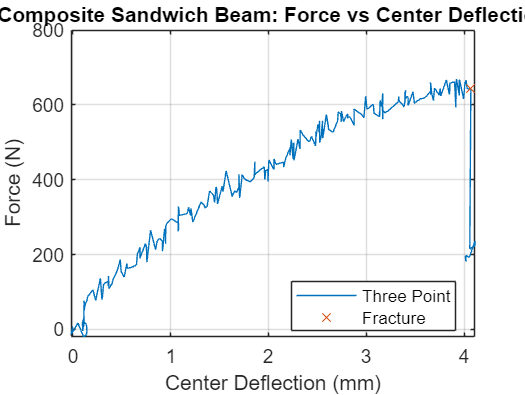

snapind = 238;


if plotting == 1
    % Plot for Al3: Force vs Laser Displacement
    figure;
    plot(cf_3pt.LD, cf_3pt.MF, 'DisplayName', 'Three Point');
    hold on; % Hold on to add the theoretical line
    plot(cf_3pt.LD(snapind), cf_3pt.MF(snapind), 'X', 'DisplayName', 'Fracture')

    % Add title, labels, and legend
    title('Composite Sandwich Beam: Force vs Center Deflection');
    xlabel('Center Deflection (mm)');
    ylabel('Force (N)');
    legend('show', 'Location', 'best');
    grid on;
    hold off; % Release the plot for other plots
end

Maximum Load and Deflection

CF_MAX_LOAD = mean(cf_3pt.MF(snapind-8:snapind)); % The value is in N
fprintf('CF_MAX_LOAD is %.2f N.\n', CF_MAX_LOAD);

CF_MAX_LOAD is 653.05 N.



CF_MAX_DEFLEC = cf_3pt.LD(snapind); % Snapped at index 238, lost of load force reading
fprintf('CF_MAX_DEFLECTION is %.2f mm.\n', CF_MAX_DEFLEC);

CF_MAX_DEFLECTION is 4.07 mm.


Fracture Prediction **(Incomplete)**

b = 30.65 % mm

b = 30.6500

t = (34.073 - 30)/2 % mm

t = 2.0365

d = b - t % mm

d = 28.6135